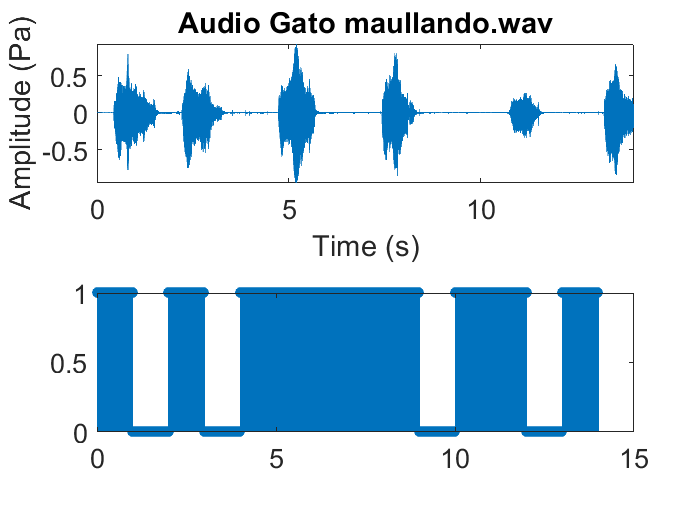

addpath("Audios\");

audio="Gato maullando.wav";

%Fuction to identify the signals as tonals or non tonals
%
% Input parameters:
%   audio= data
%
%Output parameters:
%tone: True if the audio is tonal or on the contrary, non tonal

[signal, fs]=audioread(audio);
signal=signal(:, 1); %only mono, not stereo
Nsignal=length(signal);  %Total samples of the signal
Ny=length(signal); 
Ts=1/fs;
t=0:Ts:Ts*(Ny - 1);
Lframe = fs;
start_slice_frame=1;
stop_slice_frame=Lframe;
tone_totals=[];
tone_totals_graphic=[];
tone_true= ones(1, Lframe);
tone_false= zeros(1, Lframe);


for i = 1:floor(length(signal)/Lframe) % Para cada trama
    a=Lframe*floor(length(signal)/Lframe);
    frame=signal(start_slice_frame:stop_slice_frame);
    ffx=fft(frame, fs);%fft with fs points
    ffx=abs(ffx/fs); %Amplitude
    fx=ffx(1:fs/2+1); %Part of interest
    f=(0:fs/2); %Frequency axis
    x=smoothdata(fx);
    x=smoothdata(x);
    M=mean(fx); %inferior threeshold

    maxs=islocalmax(x,'MinProminence',M);
    number_of_tones=sum(maxs(:)==1);


    if number_of_tones<=1                                                      
        tone="False";
        tone_totals_graphic=[tone_totals_graphic tone_false];
    else
        tone="True";
        tone_totals_graphic=[tone_totals_graphic tone_true];
    end
    

    tone_totals=[tone_totals tone];
    start_slice_frame=start_slice_frame+Lframe;
    stop_slice_frame=stop_slice_frame+Lframe;
end

subplot 211
plot(t(1:a),signal(1:a)), xlabel('Time (s)'), ylabel('Amplitude (Pa)'), axis tight;
set(gca,'FontSize',16);
title("Audio "+audio);
subplot 212
stem(t(1:a),tone_totals_graphic(1:a));
set(gca,'FontSize',16);

disp(tone_totals);

  Columns 1 through 5

    "True"    "False"    "True"    "False"    "True"

  Columns 6 through 10

    "True"    "True"    "True"    "True"    "False"

  Columns 11 through 14

    "True"    "True"    "False"    "True"

